# Fig. 1905 Stat of Doppler using LME

Load and plot data.

clear;
path(path,'../../_alg');  
path(path,'../../matlab-alg');
path(path,'../../matlab-lib');

tbFraw = readtable('data1905.xlsx');
tbFraw.Grp = categorical(tbFraw.Grp);
tbFraw.VesselType = categorical(tbFraw.VesselType);
tbFraw.Subj = categorical(tbFraw.Subj);
tbFraw.Vessel = categorical(tbFraw.Vessel);
tbFraw(:,5:11).Variables = abs(tbFraw(:,5:11).Variables);

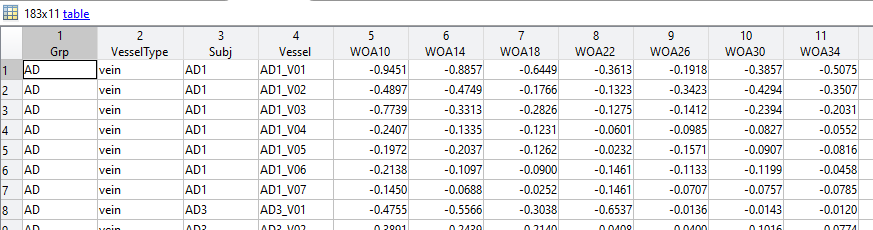

Tukey boxplot

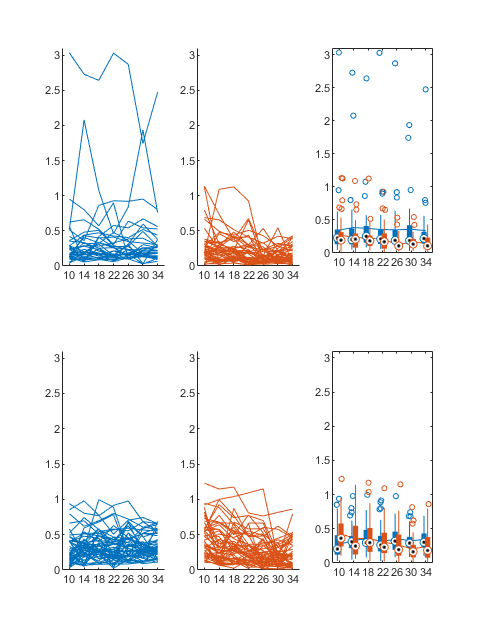

t = (10:4:34);  nt = length(t);
faWT = tbFraw(tbFraw.Grp == "WT" & tbFraw.VesselType == "artery",5:11).Variables;
fvWT = tbFraw(tbFraw.Grp == "WT" & tbFraw.VesselType == "vein",5:11).Variables;
faAD = tbFraw(tbFraw.Grp == "AD" & tbFraw.VesselType == "artery",5:11).Variables;
fvAD = tbFraw(tbFraw.Grp == "AD" & tbFraw.VesselType == "vein",5:11).Variables;

clr = lines(2);
figure('position',[.1 .1 3/4 4/4]*640);
for ivt=1:2
    for id=1:2
        if (id == 1),  if (ivt == 1)  f = faWT;  else,  f = fvWT;  end
        else,  if (ivt == 1)  f = faAD;  else,  f = fvAD;  end;  end
        subplot(2,3,id+(ivt-1)*3);  
            for iv=1:size(f,1)
                line(t,f(iv,:),'color',clr(id,:));
            end
            xlim([t(1)-2 t(end)+2]);  ylim([0 3.1]);
            set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
    end 
end 
subplot(2,3,3);  hold on; 
    line(t,mean(faWT,1),'color',clr(1,:));
    line(t,mean(faAD,1),'color',clr(2,:));
    boxplot(faWT,'plotstyle','compact','colors',clr(1,:),'positions',t-0.5);
    boxplot(faAD,'plotstyle','compact','colors',clr(2,:),'positions',t+0.5);
    xlim([t(1)-2 t(end)+2]);  ylim([0 3.1]);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
subplot(2,3,6);  hold on; 
    line(t,mean(fvWT,1),'color',clr(1,:));
    line(t,mean(fvAD,1),'color',clr(2,:));
    boxplot(fvWT,'plotstyle','compact','colors',clr(1,:),'positions',t-0.5);
    boxplot(fvAD,'plotstyle','compact','colors',clr(2,:),'positions',t+0.5);
    xlim([t(1)-2 t(end)+2]);  ylim([0 3.1]);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));

- AD showed a clear trend of decreasing flow, in both arteries and veins.

# T-test

Plot data.

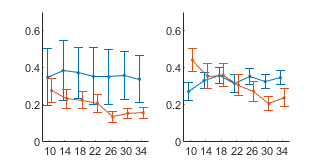

figure('position',[.1 .1 2/4 1/4]*640);
for ivt=1:2
    if (ivt == 1),  fWT = faWT;  fAD = faAD;  else,  fWT = fvWT;  fAD = fvAD;  end
    subplot(1,2,ivt);  hold on;
    for id=1:2
        if (id == 1),  f = fWT;  else,  f = fAD;  end;
        errorbar(t-0.5+(id-1),mean(f,1),tinv(0.95,size(f,1)-1)*std(f,0,1)/sqrt(size(f,1)),'color',clr(id,:),'marker','.');
        xlim([t(1)-2 t(end)+2]);  ylim([0 0.7]);
        set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
    end
end

- lower arteriolar flow in AD from 22-26 woa

- lower venular flow in AD from 26 woa

- ***Higher venular flow in AD at 10 woa: related to the AD's larger vessel diameter at 10 woa?***

## Paired t-test vs t1 (wk 10)

for ivt=1:2
    if (ivt == 1),  fWT = faWT;  fAD = faAD;  else,  fWT = fvWT;  fAD = fvAD;  end
    h = zeros(2,nt);
    for id=1:2
        if (id == 1),  f = fWT;  else,  f = fAD;  end;
        for it=1:nt
            h(id,it) = ttest(f(:,1),f(:,it));
        end
    end
    h
end

h =    NaN     0     0     0     0     0     0
   NaN     0     0     0     1     1     1


h =    NaN     1     1     0     1     1     1
   NaN     1     1     1     1     1     1


- Arteriole: WT showed NS change until 34 woa.  AD showed a decrease from 26 woa.

- Venule: Both AD and WT showed significant changes for all woas except for WT's 22 woa.

T-test analysis was vulnerable to large noise at a specific time point (e.g., WT's t = 22 woa).

## T-test of AD vs. WT

for ivt=1:2
    if (ivt == 1),  fWT = faWT;  fAD = faAD;  else,  fWT = fvWT;  fAD = fvAD;  end
    h2 = zeros(1,nt);
    for it=1:nt
        h2(it) = ttest2(fAD(:,it),fWT(:,it));
    end
    h2
end

h2 =      0     0     0     0     1     1     1


h2 =      1     0     0     0     0     1     1


- Artery: AD showed lower flow from 26 woa.

- Venule: AD was higher at 10 woa, and became lower from 30 woa.

# LME

Prepare table.

tbF = stack(tbFraw,5:11,"IndexVariableName","WeekStr","NewDataVariableName","Flow");
no = height(tbF);
tbF.Week = zeros(no,1);
for io=1:no
    wk = string(tbF(io,:).WeekStr);
    wk = extractBetween(wk,4,5);
    tbF(io,:).Week = str2num(wk);
end

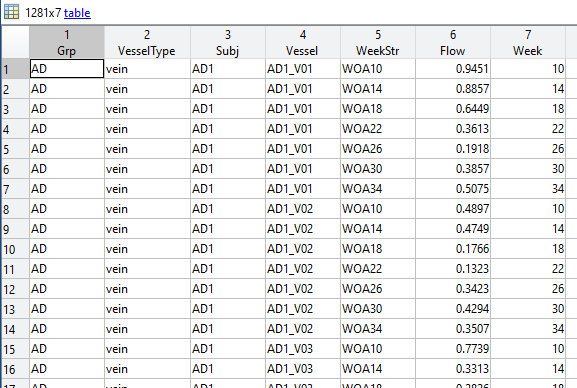

## Artery WT - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbFsub = tbF(tbF.Grp == "WT" & tbF.VesselType == "artery",:);  ivt = 1;  id = 1;
nos = height(tbFsub);

lme1 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             231
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC       BIC    LogLikelihood    Deviance
    326.23    340    -159.12          318.23  

Fixed effects coefficients (95% CIs):
    Name            Estimate       SE           tStat       DF     pValue        Lower         Upper    
    'Offset'            0.37843     0.092769      4.0793    229    6.2387e-05       0.19564      0.56122
    'Slope'         -0.00092511    0.0039629    -0.23344    229       0.81563    -0.0087335    0.0068833

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate      Lower    Up

lme2 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             231
    Fixed effects coefficients           2
    Random effects coefficients         33
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC       LogLikelihood    Deviance
    -10.678    3.0921    9.3388           -18.678 

Fixed effects coefficients (95% CIs):
    Name            Estimate       SE           tStat       DF     pValue        Lower         Upper    
    'Offset'            0.37843      0.08513      4.4453    229    1.3678e-05       0.21069      0.54617
    'Slope'         -0.00092511    0.0014539    -0.63629    229       0.52522    -0.0037899    0.0019396

Random effects covariance parameters (95% CIs):
Group: Vessel (33 Levels)
    Name1         Name2         Type         Estimate    

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.0002    0.8797


The random effect should be unknown **vessel**-specific variations, not subject-specific.

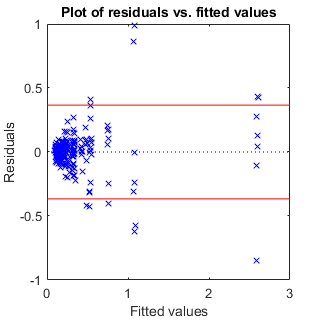

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             220
    Fixed effects coefficients           2
    Random effects coefficients         33
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -226.02    -212.44    117.01           -234.02 

Fixed effects coefficients (95% CIs):
    Name            Estimate       SE            tStat       DF     pValue       Lower         Upper    
    'Offset'             0.3662      0.080638      4.5412    218    9.252e-06       0.20727      0.52513
    'Slope'         -0.00043023    0.00083206    -0.51707    218      0.60563    -0.0020701    0.0012097

Random effects covariance parameters (95% CIs):
Group: Vessel (33 Levels)
    Name1         Name2         Type         Estimate  

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme2     4     -10.678     3.0921    9.3388                               
    lme3     4     -226.02    -212.44    117.01    215.34    0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.8797    0.9405


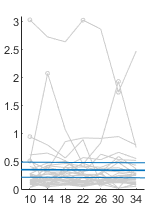

No significant difference from 10 woa, p(t1,tend)=0.927


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  if (ivt+id == 2),  limY = [0 3.1];  else,  limY = [0 1.5];  end
lme = lme3;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

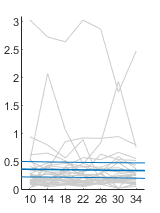

No significant difference from 10 woa, p(t1,tend)=0.847


lme = lme2;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

The slope was NS (p=0.6).

## Artery WT - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

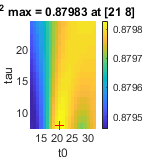

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,5) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

***R2 max at the boundary:  Don't trust this fitting.  Below is just FYI.***

lmeWTa = lme2;

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             231
    Fixed effects coefficients           2
    Random effects coefficients         33
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC       LogLikelihood    Deviance
    -10.858    2.9114    9.4291           -18.858 

Fixed effects coefficients (95% CIs):
    Name               Estimate     SE          tStat       DF     pValue        Lower        Upper   
    'Offset'             0.36875    0.080114      4.6028    229    6.9083e-06      0.21089     0.52661
    'Amplitude'        -0.019893    0.025985    -0.76554    229       0.44474    -0.071094    0.031308

Random effects covariance parameters (95% CIs):
Group: Vessel (33 Levels)
    Name1         Name2         Type         Estimate    Lo

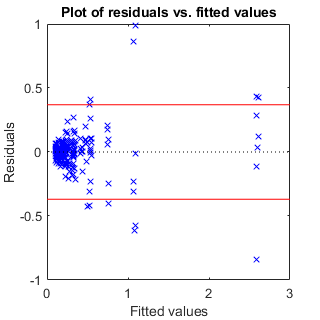

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})
figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');

thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');
iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(5.89*tau)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             220
    Fixed effects coefficients           2
    Random effects coefficients         33
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -226.02    -212.44    117.01           -234.02 

Fixed effects coefficients (95% CIs):
    Name               Estimate     SE         tStat       DF     pValue        Lower       Upper  
    'Offset'             0.39789    0.11193      3.5547    218    0.00046399     0.17728     0.6185
    'Amplitude'        -0.081461    0.15751    -0.51719    218       0.60554    -0.39189    0.22897

Random effects covariance parameters (95% CIs):
Group: Vessel (33 Levels)
    Name1         Name2         Type         Estimate    Lower    

    'FixedEffectPredictors', {'Offset','Amplitude'}, ...

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme5     4     -10.858     2.9114    9.4291                               
    lme6     4     -226.02    -212.44    117.01    215.16    0          0     


    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...

ans =     0.8797    0.8798


    'Exclude',iol)

ans =     0.9405    0.9405


compare(lme5,lme6)
[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]
[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

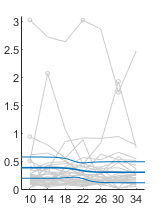

No significant difference from 10 woa, p(t1,tend)=0.606


lme = lme6;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));

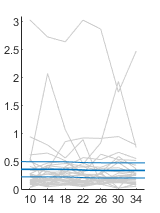

No significant difference from 10 woa, p(t1,tend)=0.861


fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;
lme = lme5;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));

fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

## Artery AD - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbFsub = tbF(tbF.Grp == "AD" & tbF.VesselType == "artery",:);  ivt = 1;  id = 2;
nos = height(tbFsub);

lme1 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             315
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -197.37    -182.36    102.69           -205.37 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE           tStat      DF     pValue        Lower         Upper    
    'Offset'           0.31809     0.028796     11.046    313    3.5661e-24       0.26143      0.37475
    'Slope'         -0.0054154    0.0012301    -4.4023    313    1.4712e-05    -0.0078357    -0.002995

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate      Lower  

lme2 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             315
    Fixed effects coefficients           2
    Random effects coefficients         45
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -266.43    -251.42    137.21           -274.43 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat      DF     pValue        Lower         Upper     
    'Offset'           0.31809      0.027832     11.429    313     1.624e-25       0.26333       0.37285
    'Slope'         -0.0054154    0.00098333    -5.5072    313    7.6112e-08    -0.0073501    -0.0034806

Random effects covariance parameters (95% CIs):
Group: Vessel (45 Levels)
    Name1         Name2         Type         Estimate  

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.0580    0.3818


The random effect should be unknown **vessel**-specific variations, not subject-specific.

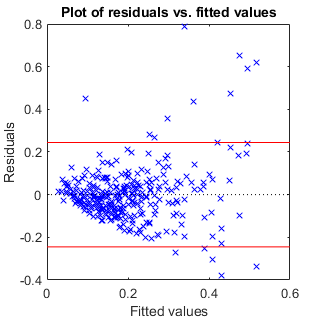

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           2
    Random effects coefficients         44
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -507.57    -492.76    257.79           -515.57 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat      DF     pValue        Lower         Upper     
    'Offset'           0.26149      0.020668     12.652    298    1.1725e-29       0.22081       0.30216
    'Slope'         -0.0037071    0.00063546    -5.8337    298    1.4111e-08    -0.0049577    -0.0024565

Random effects covariance parameters (95% CIs):
Group: Vessel (44 Levels)
    Name1         Name2         Type         Estimate  

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme2     4     -266.43    -251.42    137.21                               
    lme3     4     -507.57    -492.76    257.79    241.15    0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.3818    0.5687


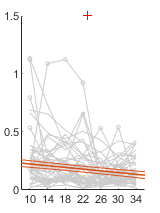

Became significantly different from 10 woa at 23 woa.


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  if (ivt+id == 2),  limY = [0 3.1];  else,  limY = [0 1.5];  end
lme = lme3;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

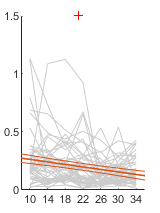

Became significantly different from 10 woa at 21 woa.


lme = lme2;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

The slope was SIG.

## Artery AD - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

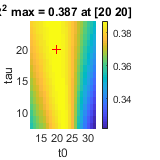

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,3) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

***R2 max was not at the boudnary.  Keep going.***

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             315
    Fixed effects coefficients           2
    Random effects coefficients         45
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -268.49    -253.48    138.25           -276.49 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE          tStat      DF     pValue        Lower       Upper   
    'Offset'            0.27011    0.021488      12.57    313    1.2945e-29     0.22783     0.31239
    'Amplitude'        -0.12502    0.021884    -5.7127    313    2.5876e-08    -0.16808    -0.08196

Random effects covariance parameters (95% CIs):
Group: Vessel (45 Levels)
    Name1         Name2         Type         Estimate    Lower    

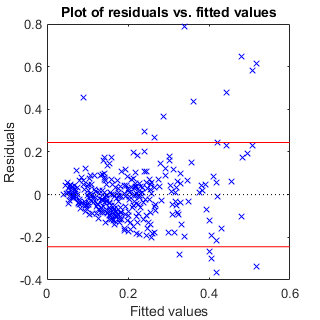

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(5.89*tau)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           2
    Random effects coefficients         44
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -507.59    -492.77    257.79           -515.59 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE         tStat      DF     pValue        Lower      Upper  
    'Offset'            1.0616     0.15196     6.9856    298    1.8565e-11    0.76249     1.3606
    'Amplitude'        -1.7484     0.29964    -5.8349    298     1.402e-08    -2.3381    -1.1587

Random effects covariance parameters (95% CIs):
Group: Vessel (44 Levels)
    Name1         Name2         Type         Estimate    Lower       Upper 

compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme5     4     -268.49    -253.48    138.25                               
    lme6     4     -507.59    -492.77    257.79    239.09    0          0     


[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.3818    0.3872


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.5687    0.5687


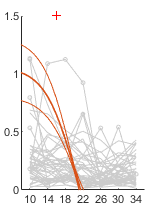

Became significantly different from 10 woa at 16 woa.


lme = lme6;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

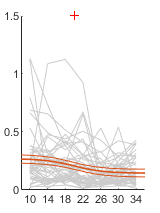

Became significantly different from 10 woa at 20 woa.


lme = lme5;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

lmeADa = lme5;

***Without outlier exclusion (which is better), R2 was higher in logistics (0.3872 vs 0.3818).  The amplitude was SIG.***

## Vein WT - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbFsub = tbF(tbF.Grp == "WT" & tbF.VesselType == "vein",:);  ivt = 2;  id = 1;
nos = height(tbFsub);

lme1 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             378
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -175.15    -159.41    91.575           -183.15 

Fixed effects coefficients (95% CIs):
    Name            Estimate     SE          tStat     DF     pValue        Lower         Upper    
    'Offset'          0.28762    0.028583    10.063    376    2.9941e-21       0.23142      0.34382
    'Slope'         0.0018656    0.001221     1.528    376       0.12736    -0.0005352    0.0042665

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate    Lower    Upper
   

lme2 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             378
    Fixed effects coefficients           2
    Random effects coefficients         54
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -373.41    -357.67    190.71           -381.41 

Fixed effects coefficients (95% CIs):
    Name            Estimate     SE            tStat     DF     pValue        Lower         Upper    
    'Offset'          0.28762      0.027035    10.639    376    2.7725e-23       0.23446      0.34078
    'Slope'         0.0018656    0.00079376    2.3504    376      0.019271    0.00030487    0.0034264

Random effects covariance parameters (95% CIs):
Group: Vessel (54 Levels)
    Name1         Name2         Type         Estimate    Lower  

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.0061    0.5897


The random effect should be unknown **vessel**-specific variations, not subject-specific.

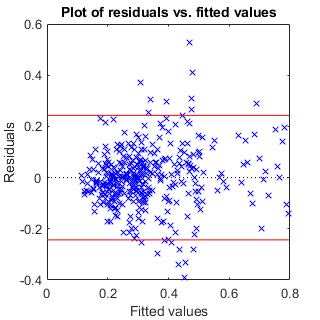

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             360
    Fixed effects coefficients           2
    Random effects coefficients         54
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC       LogLikelihood    Deviance
    -511.65    -496.1    259.82           -519.65 

Fixed effects coefficients (95% CIs):
    Name            Estimate     SE            tStat     DF     pValue        Lower          Upper    
    'Offset'          0.30047      0.025211    11.919    358    8.2493e-28        0.25089      0.35005
    'Slope'         0.0012322    0.00063018    1.9553    358      0.051324    -7.1231e-06    0.0024715

Random effects covariance parameters (95% CIs):
Group: Vessel (54 Levels)
    Name1         Name2         Type         Estimate    Lower 

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme2     4     -373.41    -357.67    190.71                               
    lme3     4     -511.65     -496.1    259.82    138.23    0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.5897    0.7323


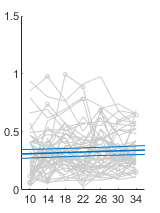

No significant difference from 10 woa, p(t1,tend)=0.351


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  if (ivt+id == 2),  limY = [0 3.1];  else,  limY = [0 1.5];  end
lme = lme3;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

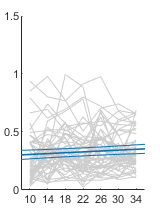

No significant difference from 10 woa, p(t1,tend)=0.167


lme = lme2;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

The slope was SIG but became NS after outlier exclusion (p=0.02 to 0.051).

## Vein WT - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

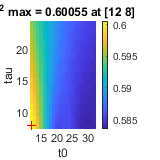

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,5) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

R2 max at the boundary, don't need to keep going.  Below is just FYI.

lmeWTv = lme2;

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             378
    Fixed effects coefficients           2
    Random effects coefficients         54
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -381.13    -365.39    194.57           -389.13 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE          tStat     DF     pValue        Lower       Upper  
    'Offset'           0.25841     0.028151    9.1793    376    2.9423e-18     0.20305    0.31376
    'Amplitude'        0.08214     0.022383    3.6698    376    0.00027786    0.038128    0.12615

Random effects covariance parameters (95% CIs):
Group: Vessel (54 Levels)
    Name1         Name2         Type         Estimate    Lower      Uppe

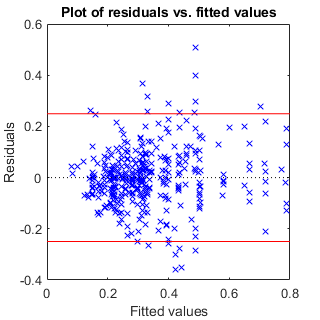

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(5.89*tau)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             360
    Fixed effects coefficients           2
    Random effects coefficients         54
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -507.31    -491.77    257.66           -515.31 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE          tStat     DF     pValue       Lower         Upper  
    'Offset'           0.19399     0.070407    2.7552    358    0.0061646      0.055525    0.33245
    'Amplitude'        0.23581      0.12158    1.9395    358     0.053222    -0.0032924    0.47491

Random effects covariance parameters (95% CIs):
Group: Vessel (54 Levels)
    Name1         Name2         Type         Estimate    Lower      U

compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme5     4     -381.13    -365.39    194.57                               
    lme6     4     -507.31    -491.77    257.66    126.18    0          0     


[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.5897    0.6006


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.7323    0.7265


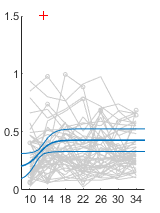

Became significantly different from 10 woa at 13 woa.


lme = lme6;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

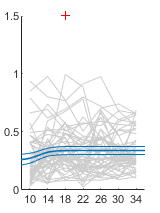

Became significantly different from 10 woa at 18 woa.


lme = lme5;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

## Vein AD - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Vessel

tbFsub = tbF(tbF.Grp == "AD" & tbF.VesselType == "vein",:);  ivt = 2;  id = 2;
nos = height(tbFsub);

lme1 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             357
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -34.136    -18.625    21.068           -42.136 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE          tStat      DF     pValue        Lower        Upper     
    'Offset'           0.49916     0.04509      11.07    355    1.1424e-24      0.41048       0.58784
    'Slope'         -0.0088835    0.001484    -5.9861    355    5.2609e-09    -0.011802    -0.0059649

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate    Lower       

lme2 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             357
    Fixed effects coefficients           2
    Random effects coefficients         51
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -226.15    -210.64    117.07           -234.15 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat      DF     pValue        Lower        Upper     
    'Offset'           0.50704      0.034234     14.811    355    5.5343e-39      0.43972       0.57437
    'Slope'         -0.0088835    0.00096512    -9.2045    355    3.0217e-18    -0.010782    -0.0069854

Random effects covariance parameters (95% CIs):
Group: Vessel (51 Levels)
    Name1         Name2         Type         Estimate    L

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.1535    0.6606


The random effect should be unknown **vessel**-specific variations, not subject-specific.

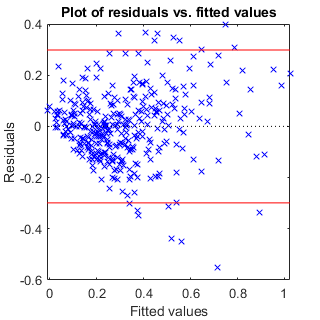

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbFsub.Week], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             340
    Fixed effects coefficients           2
    Random effects coefficients         51
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -333.34    -318.03    170.67           -341.34 

Fixed effects coefficients (95% CIs):
    Name            Estimate      SE            tStat      DF     pValue        Lower         Upper     
    'Offset'           0.48576      0.033238     14.614    338    7.8802e-38       0.42038       0.55114
    'Slope'         -0.0078482    0.00080275    -9.7767    338    4.8148e-20    -0.0094272    -0.0062692

Random effects covariance parameters (95% CIs):
Group: Vessel (51 Levels)
    Name1         Name2         Type         Estimate  

compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme2     4     -226.15    -210.64    117.07                               
    lme3     4     -333.34    -318.03    170.67    107.2     0          0     


[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.6606    0.7565


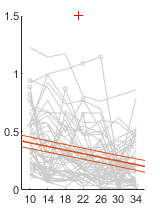

Became significantly different from 10 woa at 21 woa.


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;  if (ivt+id == 2),  limY = [0 3.1];  else,  limY = [0 1.5];  end
lme = lme3;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

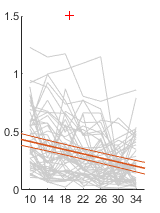

Became significantly different from 10 woa at 19 woa.


lme = lme2;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) .* ti;
fitse = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );
secfig1905a;

The slope was SIG.

## Vein AD - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

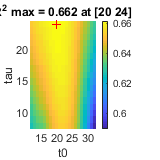

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*640);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max = ' num2str(r2max,3) ' at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

***R2 max at the boudary***.  tau = 48 woa when ctau is upto 48.  tau > 24 has no meaning because the total measurement time was 24 weeks.

lme5 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(tau/5.89)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             357
    Fixed effects coefficients           2
    Random effects coefficients         51
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -226.95    -211.44    117.47           -234.95 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE          tStat      DF     pValue        Lower       Upper   
    'Offset'            0.43382    0.029922     14.498    355    9.7557e-38     0.37497     0.49267
    'Amplitude'        -0.21556    0.023278    -9.2599    355    1.9923e-18    -0.26134    -0.16977

Random effects covariance parameters (95% CIs):
Group: Vessel (51 Levels)
    Name1         Name2         Type         Estimate    Lower    

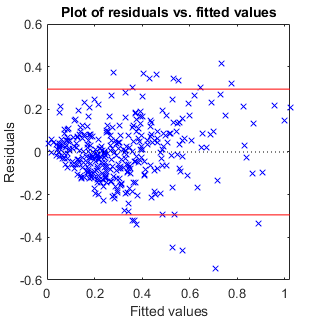

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbFsub.Week-t0)/(5.89*tau)))], tbFsub.Flow, [ones(nos,1)], tbFsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             340
    Fixed effects coefficients           2
    Random effects coefficients         51
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -333.13    -317.81    170.56           -341.13 

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE         tStat      DF     pValue        Lower      Upper  
    'Offset'            2.5732     0.23093     11.143    338    9.0227e-25      2.119     3.0275
    'Amplitude'        -4.4925      0.4551    -9.8715    338     2.316e-20    -5.3877    -3.5973

Random effects covariance parameters (95% CIs):
Group: Vessel (51 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper  


compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lme5     4     -226.95    -211.44    117.47                               
    lme6     4     -333.13    -317.81    170.56    106.18    0          0     


[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.6606    0.6616


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.7565    0.7537


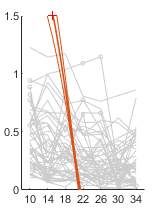

Became significantly different from 10 woa at 15 woa.


lme = lme6;
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

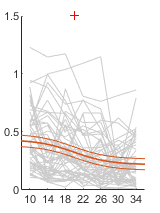

Became significantly different from 10 woa at 20 woa.


lme = lme5;  iol = [];
est = lme.Coefficients.Estimate;  se = lme.Coefficients.SE;  covr = lme.CoefficientCovariance;
fitmean = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
fitse = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );
secfig1905a;

lmeADv = lme5;

***Without outlier exclusion (which is better), R2 was higher in logistics (0.6616 vs 0.6606).  The amplitude was SIG.***

save("fig1905 stat Doppler.mat");

## Compare AD vs WT

nvWT = size(fWT,1);
est = lmeWT.Coefficients.Estimate;  se = lmeWT.Coefficients.SE;  covr = lmeWT.CoefficientCovariance;
vdfitmeanWT = est(1) + est(2) .* ti;
vdfitseWT = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );

nvAD = size(fAD,1);
t0 = 12;  tau = 10;
est = lmeAD.Coefficients.Estimate;
se = lmeAD.Coefficients.SE;
covr = lmeAD.CoefficientCovariance;
vdfitmeanAD = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
vdfitseAD = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );

figure('position',[.1 .1 1/4 1/4]*640);
line(ti,vdfitmeanWT, 'color',clr(1,:), 'linewidth',1.5);
line(ti,vdfitmeanWT+tinv(0.95,nvWT)*vdfitseWT, 'color',clr(1,:));
line(ti,vdfitmeanWT-tinv(0.95,nvWT)*vdfitseWT, 'color',clr(1,:));
line(ti,vdfitmeanAD, 'color',clr(2,:), 'linewidth',1.5);
line(ti,vdfitmeanAD+tinv(0.95,nvAD-1)*vdfitseAD, 'color',clr(2,:));
line(ti,vdfitmeanAD-tinv(0.95,nvAD-1)*vdfitseAD, 'color',clr(2,:));
xlim([t(1)-2 t(end)+2]);  ylim([10 65]);
p = zeros(size(ti));
for it=1:length(p)
    p(it) = GetP_studentT([vdfitmeanWT(it) (vdfitseWT(it)*sqrt(nvWT)) nvWT], [vdfitmeanAD(it) (vdfitseAD(it)*sqrt(nvAD)) nvAD]);
end
p<0.05

- Not good to present

it0 = find(ti==10);
vdfitmeanWTn = vdfitmeanWT / vdfitmeanWT(it0);
vdfitseWTn = vdfitseWT / vdfitmeanWT(it0);
vdfitmeanADn = vdfitmeanAD / vdfitmeanAD(it0);
vdfitseADn = vdfitseAD / vdfitmeanAD(it0);

figure('position',[.1 .1 1/4 1/4]*640);
line(ti,vdfitmeanWTn, 'color',clr(1,:), 'linewidth',1.5);
line(ti,vdfitmeanWTn+tinv(0.95,nvWT)*vdfitseWTn, 'color',clr(1,:));
line(ti,vdfitmeanWTn-tinv(0.95,nvWT)*vdfitseWTn, 'color',clr(1,:));
line(ti,vdfitmeanADn, 'color',clr(2,:), 'linewidth',1.5);
line(ti,vdfitmeanADn+tinv(0.95,nvAD-1)*vdfitseADn, 'color',clr(2,:));
line(ti,vdfitmeanADn-tinv(0.95,nvAD-1)*vdfitseADn, 'color',clr(2,:));
xlim([t(1)-2 t(end)+2]);  ylim([0 2]);